# Noise Measurements Lab

**Johnson Noise**

With the setup as indicated in figure 1.2 and table 1.1, connect a short, one foot, coaxial cable directly from A input to B input. Your VRMS output reading from this setup should be about 20 mVAC or less if the equipment is working properly while running on battery. 

Measured around Vrms =  4.9 +/- 0.3 mVAC		

1.3: Testing Attenuator - Given a 5.000 V rms input sigma from the function generator, we measure a 5.009 +/- 0.001 mVAC

Measuring Gain and Bandwidth - Setting the function generator to a 0.1000 V rms sine wave at 2.000 kHz, we measure ...

V_in = 5.000; % v rms

V_out = 0.005009; % v rms

V_out_err = 0.000001; % v rms

V_in_err = 0.0001; % V rms

attenuation = V_out/V_in;

## Preliminary Analysis

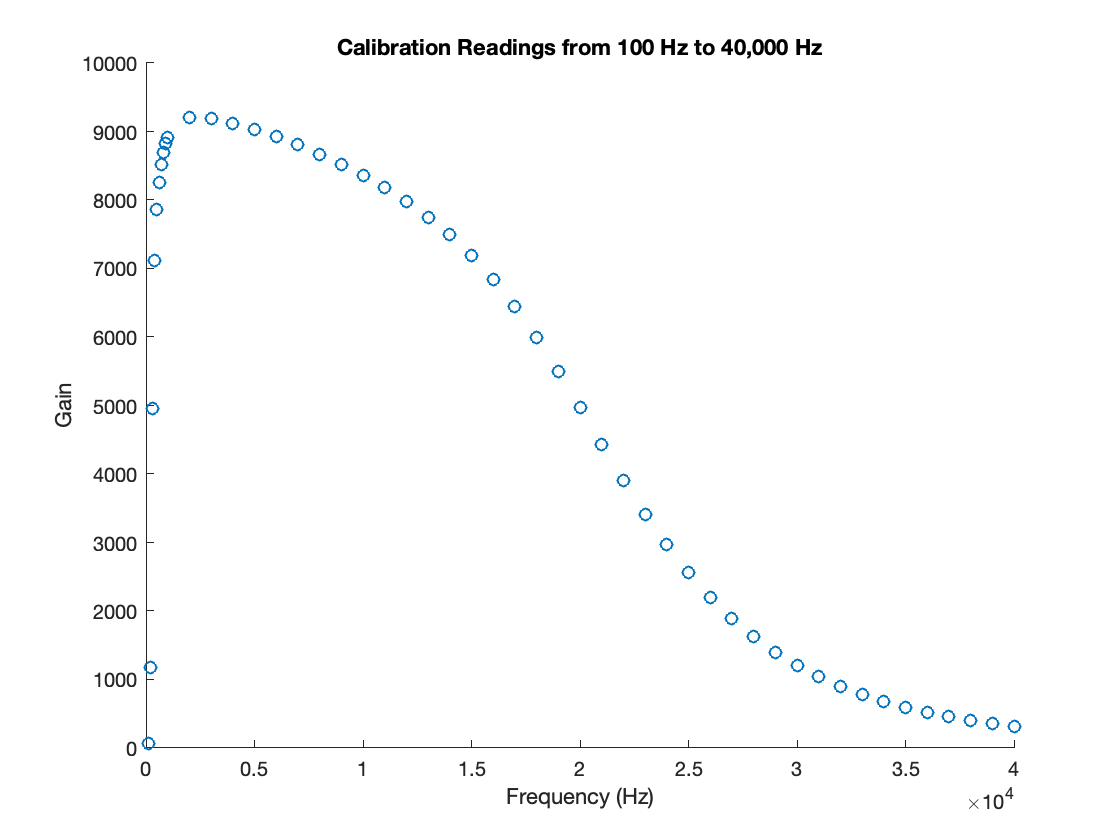


attenuation = 1/998.2;
calibration_data = dlmread('Noise Lab.csv',',',1,0);
freq = calibration_data(:,1);
V_in = calibration_data(:,2);
V_in_err = calibration_data(:,3);
V_out = calibration_data(:,4);
V_out_err = calibration_data(:,5);
V_in = V_in.*attenuation;
V_in_err = V_in_err.*attenuation;
gain = V_out./V_in;

scatter(freq,gain)
xlabel("Frequency (Hz)")
ylabel("Gain")
title("Calibration Readings from 100 Hz to 40,000 Hz")

Bandwidth = 19000;
max_gain = findpeaks(gain);
G2B_estimated = max_gain^2*Bandwidth;

% Perform this measurement for each R, 
% Divide y axis by the corresponding g s b values
% TODO: get error propagation for I measured
G2B = trapz(freq,gain.^2);
fprintf([' Maximum Gain: %.0f \n ' ...
    'Bandwidth Estimate: %.0f Hz \n ' ...
    'G^2B Estimate: %.4g \n ' ...
    'G^2B Calculated: %.4g \n '],...
    max_gain,Bandwidth,G2B_estimated,G2B)

 Maximum Gain: 9203 
 Bandwidth Estimate: 19000 Hz 
 G^2B Estimate: 1.609e+12 
 G^2B Calculated: 1.354e+12 
 

### Obtain a Value for K by Plotting *V**2**R */ (4 *T G^2**B*) vs. *R. *						

% To note: wire with coating gives different V_zero
JohnsonData = dlmread('JohnsonData.csv',',',1,0);
R = JohnsonData(:,1);
V_R = JohnsonData(:,2);
V_R_err = JohnsonData(:,3);
V_zero = JohnsonData(1,2);
V_zero_err = JohnsonData(1,3);
V_J_out = sqrt(V_R(2:end).^2 - V_zero^2);
T = 295; % degrees Kelvin
T_err = 3; % degrees Kelvin

x = R;
y = V_R.^2/(4*G2B*T);
fit_vals = LSQfit(x,y,V_R_err);

'LSQfit' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/cameronlaedtke/MatlabProjects/PHYS 4052W

Change the MATLAB current folder or add its folder to the MATLAB path.

k = fit_vals(1,2)
scatter(x,y)
xlabel('Resistance (Ohms)')
ylabel('$\frac{V_{R}^2}{4 T G^2 B}$','Interpreter','latex')

## Additional Analysis and Correction Factor

clear all
attenuation = 1/998.2;
calibration_data = dlmread('Noise Lab.csv',',',1,0);
freq = calibration_data(:,1);
V_in = calibration_data(:,2);
V_in_err = calibration_data(:,3);
V_out = calibration_data(:,4);
V_out_err = calibration_data(:,5);
V_in = V_in.*attenuation;
V_in_err = V_in_err.*attenuation;
gain = V_out./V_in;

% For correction constant
Johnson2 = dlmread('JohnsonData2.csv',',',1,0);
R = Johnson2(:,1);
V_R = Johnson2(:,2);
V_R_err = Johnson2(:,3);
V_zero = Johnson2(:,4); 
V_zero_err = Johnson2(:,5);
V_J_out = sqrt(V_R.^2 - V_zero.^2);


### *Plot V**2**R */ (4 *T G^2B(R,C)*) vs. *R*,  Data should fall on straight line for "Correct" C value 				

C0 = 29*10^-12;
intg2C = zeros(1,length(R));
for i = 1:length(R)
    intg2C(i) = ...
      trapz(freq,(gain.^2)./(1+((2*pi.*freq.*R(i)*C0).^2)));
end
intg2C = intg2C';

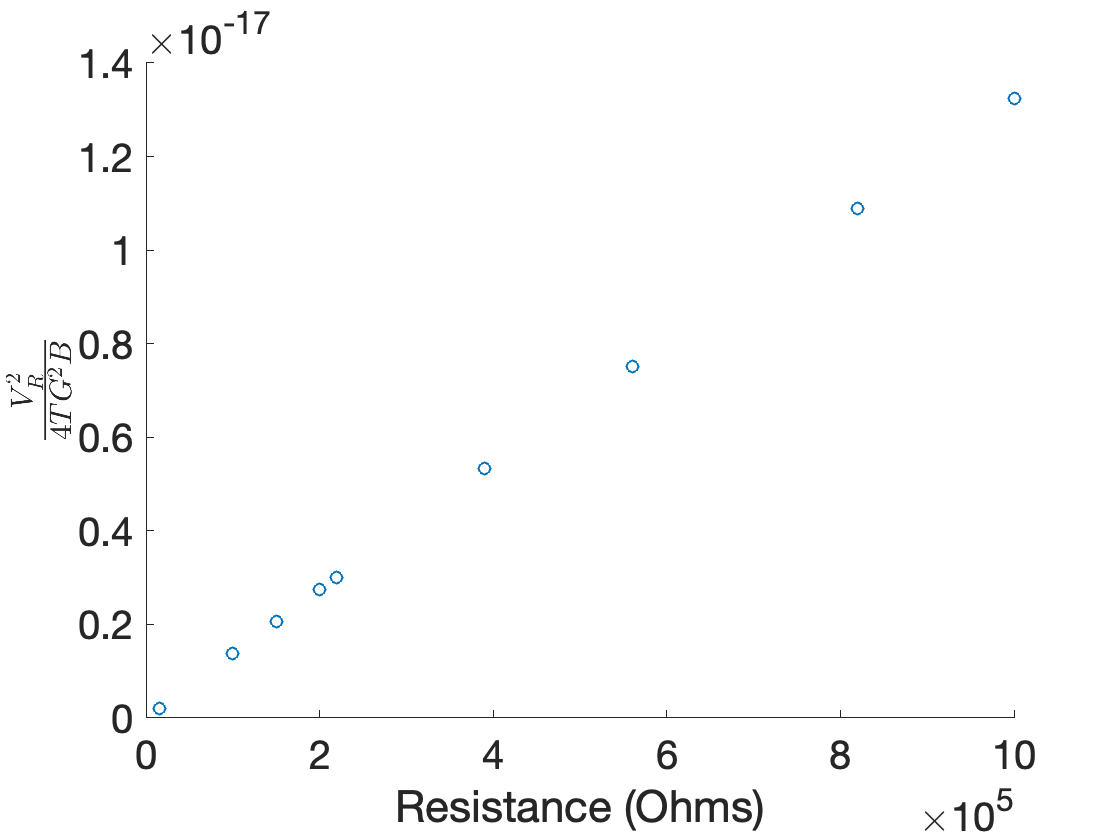

T = 295; % degrees Kelvin
T_err = 3; % degrees Kelvin

x = R;
y = V_R.^2./(4*intg2C*T);

dydVR = V_R./(2*intg2C*T);
dydT = -(V_R.^2./(4*intg2C*T^2))

sig_y = sqrt(V_R_err.^2.*dydVR.^2+T_err^2.*dydT.^2)


% sig_y = sqrt((V_R.^4.*T_err.^2)./(16*intg2C.^2.*T^4) +...
%     (V_R.^2.*V_R_err.*R.^2)./(4*intg2C.^2.*T^2));

scatter(x,y)
xlabel('Resistance (Ohms)')
ylabel('$\frac{V_{R}^2}{4 T G^2 B}$','Interpreter','latex')
set(gca,'FontSize',20)

## Shot Noise

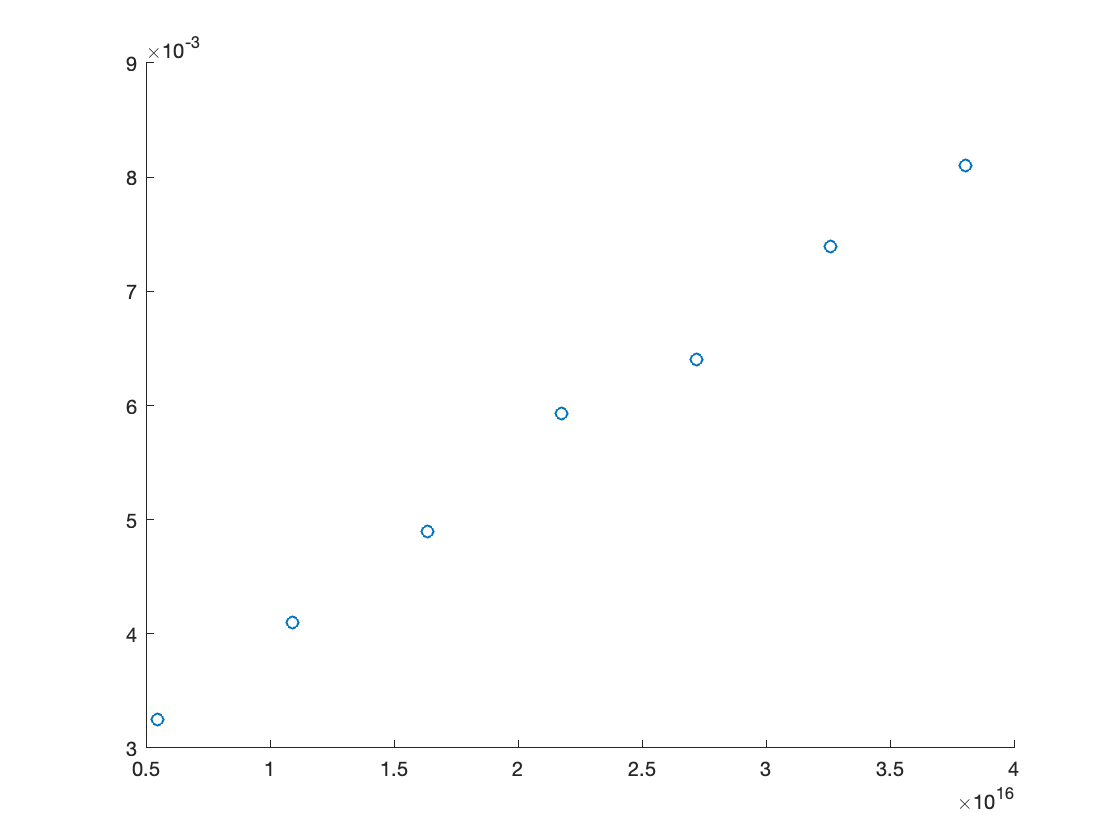

% Set the switch on shielded box to "shot" position
% photodiode connected across resistor and BNC output
% Adjusted LED intensity and observe the range of Vave 
% as a DC voltage across R

% Range of Vave: 0.00001V to 0.185 V

R_100k = 100000; % ohms
shot_100k = dlmread('ShotNoise.csv',',',[1 0 7 3]).*(1/1000);
V_ave_100k = shot_100k(:,1);
V_ave_err_100k = shot_100k(:,2);
V_rms_100k = shot_100k(:,3);
V_rms_Err_100k = shot_100k(:,4);

x = 2*R_100k.*V_ave_100k.*intg2C;
y = V_rms_100k.^2;
scatter(x,y)

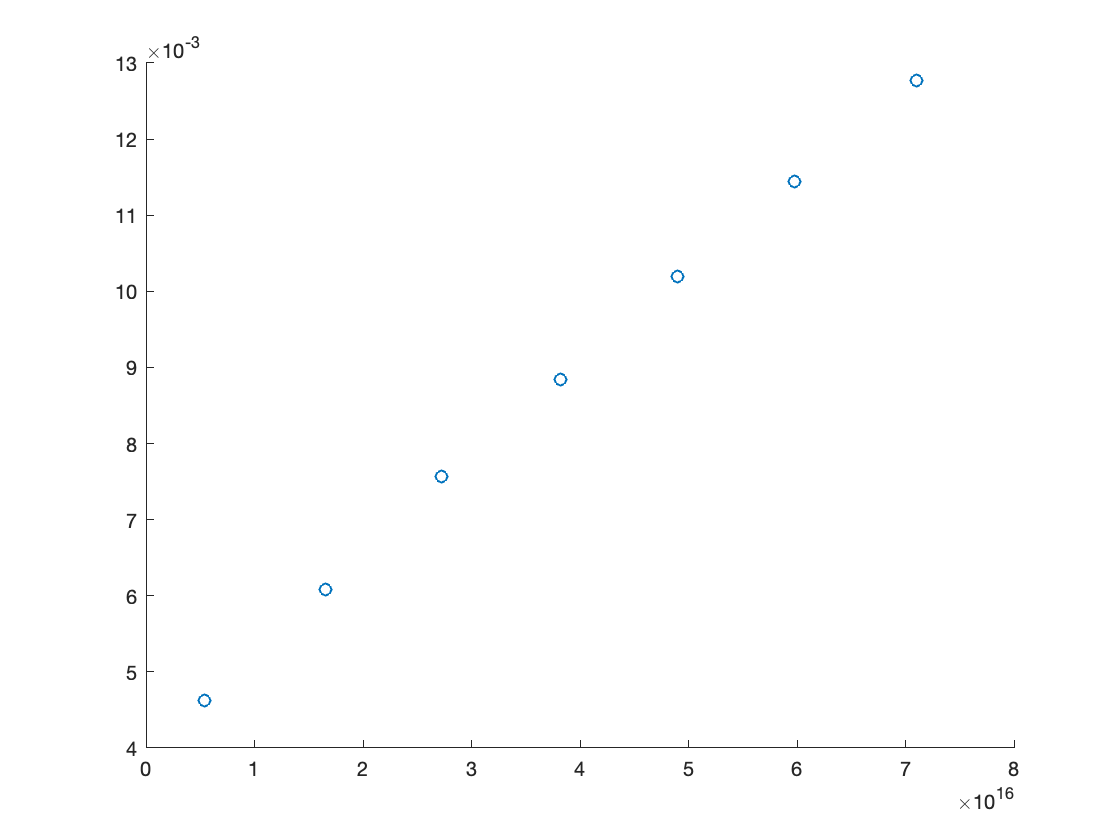

xlabel('Resistance (Ohms)')
ylabel('$\frac{V_{R}^2}{4 T G^2 B}$','Interpreter','latex')
fit_vals = LSQfit(x,y,V_rms_Err_100k);
slope1 = fit_vals(1,2);
intercept1 = fit_vals(1,1);

R_200k = 200000; % ohms
shot_200k = dlmread('ShotNoise.csv',',',[10,0,16,3]).*(1/1000);
V_ave_200k = shot_200k(:,1);
V_ave_err_200k = shot_200k(:,2);
V_rms_200k = shot_200k(:,3);
V_rms_Err_200k = shot_200k(:,4);

x = 2*R_200k.*V_ave_200k.*intg2C;
y = V_rms_200k.^2;
scatter(x,y)

fit_vals = LSQfit(x,y,V_rms_Err_200k);
slope2 = fit_vals(1,2)

slope2 = 1.2481e-19

intercept2 = fit_vals(1,1)

intercept2 = 0.0040

syms R V_R T G2B y(R,G2B) sigma_V_R sigma_T
y = V_R^2/(4*T*G2B)

$$y = \frac{{V_{R}}^{2}}{4\,\mathrm{G2B}\,T}$$

dydV_R = diff(y,V_R)

$$dydV\_R = \frac{V_{R}}{2\,\mathrm{G2B}\,T}$$

dydT = diff(y,T)

$$dydT = -\frac{{V_{R}}^{2}}{4\,\mathrm{G2B}\,T^{2}}$$

sigma_y = sqrt(sigma_V_R^2*dydV_R^2+sigma_T^2*dydT^2)

$$sigma\_y = \sqrt{\frac{{V_{R}}^{4}\,{\sigma_{T}}^{2}}{16\,{\mathrm{G2B}}^{2}\,T^{4}}+\frac{{V_{R}}^{2}\,{\sigma_{V,R}}^{2}}{4\,{\mathrm{G2B}}^{2}\,T^{2}}}$$

simplify(sigma_y)

$$ans = \sqrt{\frac{{V_{R}}^{2}\,\left(4\,T^{2}\,{\sigma_{V,R}}^{2}+{V_{R}}^{2}\,{\sigma_{T}}^{2}\right)}{16\,{\mathrm{G2B}}^{2}\,T^{4}}}$$



dydV_R = V_R./(2*intg2C*T);
dydT = -(V_R.^2./(4*intg2C*T^2))